restoredefaultpath
addpath C:\Users\User\Cloud-Drive\BigFiles\libs\fieldtrip-20230223
ft_defaults

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

addpath C:\Users\User\Cloud-Drive\AnatArzi\eeglab2023.0

args = {};
args.subs = {'08','09','10','11','13','14','15','16','17','19','20','21','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'}; % add 23 to night ones
args.ft_cond_dir= sprintf('C:\\Users\\User\\Cloud-Drive\\BigFiles\\OmissionExpOutput\\ft_erpAnalysis\\data_in_ft_cond_fomat');
args.bl = 100;
args.contrasts = {{'OEf5','OR'},{'OEf6','OR'},{'OFFirst5','ORFirst5'},{'OEf6','ORf6'}};
args.pre_vs_post_conds_names = {'OR','OEf5'};
args.output_main_dir = sprintf('C:\\Users\\User\\Cloud-Drive\\BigFiles\\OmissionExpOutput\\ft_erpAnalysis\\spatiotemp_clusterPerm');

args.wake_files_name_suffix = 'wake_morning_referenced'; %wake_morning_referenced, wake_night_referenced, wake_all_referenced

subs = args.subs;
wake_files_name_suffix = args.wake_files_name_suffix;
ft_cond_dir = args.ft_cond_dir;
bl = args.bl;
contrasts = args.contrasts;
pre_vs_post_conds_names = args.pre_vs_post_conds_names;
output_main_dir = args.output_main_dir;
%%%%%%%%%%%%%%%%%%%%%%%%%%
cond_rand_name ='OR';
f = funcs_spatioTemporalAnalysis();
imp = ft_importer(subs,ft_cond_dir,bl,wake_files_name_suffix);
[imp,neig] = imp.get_neighbours(imp);

using electrodes specified in the configuration
there are on average 7.4 neighbours per channel
the call to "ft_prepare_neighbours" took 0 seconds


[imp,timelock_OR] = imp.get_cond_timelocked(imp,cond_rand_name);
electrodes = timelock_OR{1}.label;
time = timelock_OR{1}.time;
time0_ind = find(time == 0, 1);
time_from0 = time(time0_ind:end);


cond1_Vs_cond2_dir = sprintf('%s\\%s\\cond1_Vs_cond2',output_main_dir,wake_files_name_suffix);
pre_vs_poststim_dir = sprintf("%s\\%s\\preStim_Vs_postStim",output_main_dir,wake_files_name_suffix);
dir_baseline_erp = sprintf('%s\\%s\\baseline_erp',output_main_dir,wake_files_name_suffix);
persub_output_dir = sprintf("%s\\%s\\per_sub_electrode",output_main_dir,wake_files_name_suffix);
mkdir(cond1_Vs_cond2_dir);

mkdir(pre_vs_poststim_dir);

mkdir(dir_baseline_erp);

mkdir(persub_output_dir);


[imp,grandavg_cond1] = imp.get_cond_grandAvg(imp,'OEf5');

the call to "ft_selectdata" took 0 seconds
computing average of avg across 27 subjects
the call to "ft_timelockgrandaverage" took 0 seconds


[imp,grandavg_cond2] = imp.get_cond_grandAvg(imp,'OR');

the call to "ft_selectdata" took 0 seconds
computing average of avg across 27 subjects
the call to "ft_timelockgrandaverage" took 0 seconds


[imp,grandavg_cond3] = imp.get_cond_grandAvg(imp,'T');

the call to "ft_selectdata" took 0 seconds
computing average of avg across 27 subjects
the call to "ft_timelockgrandaverage" took 0 seconds


%[imp,grandavg_cond4] = imp.get_cond_grandAvg(imp,'A');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
cfg = [];
cfg.showlabels  = 'yes';
cfg.interactive  = 'no';


figure; ft_multiplotER(cfg,grandavg_cond1,grandavg_cond2)

the call to "ft_selectdata" took 0 seconds
creating layout from data.elec
creating layout for eeg system


%blue - 1, red -2, green -3, purple - 4
text(0.5,0.35,'1','color','b') ;
text(0.5,0.3,'2','color','r');
text(0.5,0.25,'3','color','g');
%text(0.5,0.2,'4','color','black');



%%
cond_name ='O';
%%%%%%%%%%%%%%%%%%
cond1_text = 'OEf5';
cond2_text = 'OR';
%%%%%%%%%%%%%%%%
    
allSub_masksSum = zeros(size(electrodes,1),size(time,2));
number_of_sub_with_sig_clusters = 0;
figure
for sub_i=1:size(subs,2)
    curr_Cond1vsCond2_stat = load( sprintf("%s\\%sVs%s_sub-%s",cond1_Vs_cond2_dir,cond1_text,cond2_text, subs{sub_i}));
    if any(curr_Cond1vsCond2_stat.prob(:)<0.2)
        allSub_masksSum = allSub_masksSum+curr_Cond1vsCond2_stat.mask;
        number_of_sub_with_sig_clusters = number_of_sub_with_sig_clusters +1;
    end
end
[imp,grandAvg_cond] = imp.get_cond_grandAvg(imp,cond_name);
for i=1:5
    cfg=[];
    cfg.colorbar = 'yes'; 
    grandAvg_cond.label = grandAvg_cond.label(:);
    starttime_i = time0_ind+((i-1)*25);
    if i<5
        endtime_i = time0_ind+(i*25);
    else
        endtime_i = size(time,2);
    end
    cfg.zlim = [0 3.5];
    
    grandAvg_cond.avg = allSub_masksSum(:,starttime_i:endtime_i);
    grandAvg_cond.time = time(starttime_i:endtime_i);
    ft_topoplotER(cfg, grandAvg_cond)
    saveas(gcf, sprintf("%s/%svs%s_ElecdAvgClustPervelance_bl-%d_time-[%.2f-%.2f].png",cond1_Vs_cond2_dir,cond1_text,cond2_text,bl,time(starttime_i),time(endtime_i)))
end


currsub_preVsPoststim.("O") = load(sprintf("%s\\preVsPoststim_bl-%d_O.mat",pre_vs_poststim_dir, bl));
cont_i  =1;
conds = {args.contrasts{cont_i}{1},args.contrasts{cont_i}{2},'O','T'};  % makes sure it's size 4 (cond1, cond2, O, T)
for pos_neg_ind=1:2
    if pos_neg_ind ==1
        clusters = {currsub_preVsPoststim.("O").posclusters.prob};
        clust_mask = currsub_preVsPoststim.("O").posclusterslabelmat;
        title_text = sprintf("PreVsPoststim %s - positive clusters",conds{3});
        pos_or_neg_text = 'pos';
    else
        clusters = {currsub_preVsPoststim.("O").negclusters.prob};
        clust_mask = currsub_preVsPoststim.("O").negclusterslabelmat;
        title_text = sprintf("PreVsPoststim %s - negative clusters",conds{3});
        pos_or_neg_text = 'neg';
    end
    for clust_ind=1:size(clusters,2)
        % curr_output_filename = sprintf("%s//clustCond-%s_contrast-%svs%s_bl-%d_clustInd-%d%s.png",pre_vs_poststim_dir,conds{3},conds{1},conds{2},bl,clust_ind,pos_or_neg_text);
        % if isfile(curr_output_filename) continue; end

        if clusters{clust_ind} > 0.05
            continue;
        end
        
        % get time-electrode mask for current cluster
        curr_clust_mask = clust_mask;
        curr_clust_mask(curr_clust_mask~=clust_ind) = 0;
        curr_clust_mask(curr_clust_mask ~= 0) = 1;
        temp = mean(curr_clust_mask,2);
        clust_electd = find(temp>0);

        % Scaling of the vertical axis for the plots below
        [imp,grandavg_cond1] = imp.get_cond_timelocked(imp,conds{1});
        [imp,grandavg_cond2] = imp.get_cond_timelocked(imp,conds{2});
        f = figure;
        for isub = 1:size(subs,2)
            subplot(5,6,isub)
            % use the rectangle to indicate the time range used later
            %rectangle('Position',[time(1) 0 (time(2)-time(1)) ymax],'FaceColor',[0.7 0.7 0.7]);
            hold on;
            % plot the lines in front of the rectangle
            plot(grandavg_cond1{isub}.time,grandavg_cond1{isub}.avg(clust_electd,:) - grandavg_cond2{isub}.avg(clust_electd,:), 'Color',[0 0 1 0.5]);
            plot(grandavg_cond1{isub}.time,mean(grandavg_cond1{isub}.avg(clust_electd,:),1) - mean(grandavg_cond2{isub}.avg(clust_electd,:),1), 'r',LineWidth=1);
            title(strcat('subject ',subs{isub}));
            xlim([-0.1 0.45]);
        end
        subplot(5,6,size(subs,2)+1);
        sgtitle(sprintf("%s cluster. Num: %d",pos_or_neg_text,clust_ind)) 
        axis off

        % plot the clusters electrodes topography
        figure();
        cfg = [];
        cfg.feedback    = 'no';
        elec = ft_read_sens('GSN-HydroCel-129.sfp'); % if Cz is ref, use GSN-HydroCel-128.sfp. If not, use 'GSN-HydroCel-129.sfp'
        cfg.elec=elec;
        layout = ft_prepare_layout(cfg);
        ft_plot_layout(layout,'label','no','box','no','chanindx',clust_electd);
    end
end

%% Plot erp of difference conditions per subject - for area
central_electrodes = [6,25,61,80,93];
frontal_electrodes = [8,9,13,14]; % E10, E11, E18, E16
parital_electrodes = [48,49,52,58,59]; % E61, E62, E67, E77, E78
temporalL_electrodes = [31,32,35] ;%E39, E40, E45

electrod_num = central_electrodes;

cond1 = 'OEf5';
cond2 = 'OR';
cond3 = 'T';
cond4 = 'A';
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Scaling of the vertical axis for the plots below
[imp,grandavg_cond1] = imp.get_cond_timelocked(imp,cond1);
[imp,grandavg_cond2] = imp.get_cond_timelocked(imp,cond2);
[imp,grandavg_cond3] = imp.get_cond_timelocked(imp,cond3);
[imp,grandavg_cond4] = imp.get_cond_timelocked(imp,cond4);
figure;
for isub = 1:size(subs,2)
    subplot(5,6,isub)
    % use the rectangle to indicate the time range used later
    %rectangle('Position',[time(1) 0 (time(2)-time(1)) ymax],'FaceColor',[0.7 0.7 0.7]);
    hold on;
    % plot the lines in front of the rectangle
    plot(grandavg_cond1{isub}.time,grandavg_cond1{isub}.avg(electrod_num,:) - grandavg_cond2{isub}.avg(electrod_num,:), 'b');
    plot(grandavg_cond1{isub}.time,grandavg_cond3{isub}.avg(electrod_num,:) - grandavg_cond4{isub}.avg(electrod_num,:), 'r');
    title(strcat('subject ',subs{isub}))
%     ylim([0 1.9e-13])
     xlim([-0.1 0.45])
end

subplot(5,6,size(subs,2)+1);
axis off

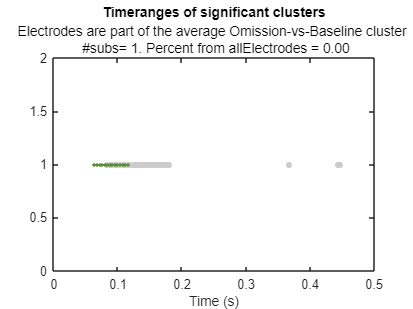

ref_input_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced';
set_per_cond_dir = 'C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\TimeAnalysis\referenced_per_cond';

subs = {'08','09','10','12','11','13','14','15','16','17','19','20','21','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};
preproc_stage = 'referenced';

sleep_files_name_suffix = strcat('sleep_',preproc_stage);
wake_night_files_name_suffix = strcat('wake_night_',preproc_stage);
wake_morning_files_name_suffix = strcat('wake_morning_',preproc_stage);
suf_i = sleep_files_name_suffix;

for sub_ind=1:size(subs,2)
    set_file_input_name =   strcat('s_',subs(sub_ind),'_',suf_i,'.set');

    eeglabsub_eeg =  pop_loadset(set_file_input_name, ref_input_dir);
    events_type_arr = {eeglabsub_eeg.event.type};

    events_cond_i = find(contains(events_type_arr,'O') & contains(events_type_arr,'_4'));

    if ~isempty(events_cond_i)  
        subs{sub_ind}
    end
end



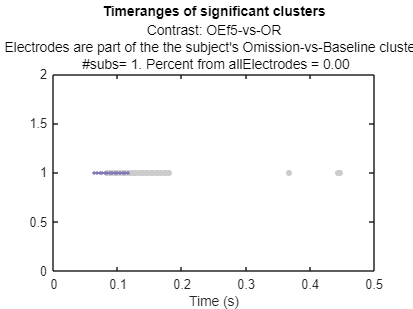

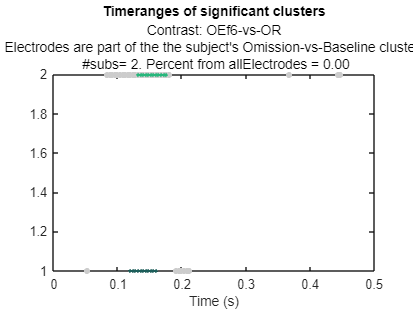

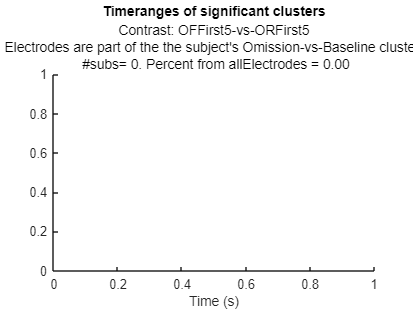

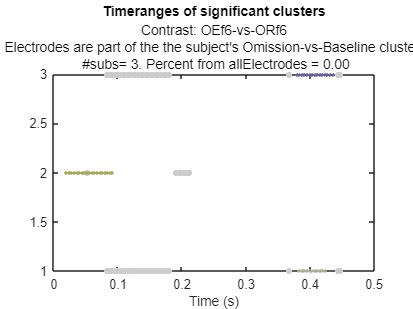

plot_allSubs_electrodes_sig_range_omissionAvgElect(contrasts, subs, electrodes,time,bl,persub_output_dir,pre_vs_poststim_dir)

plot_allSubs_electrodes_sig_range_omissionPerSubElect(contrasts, subs, electrodes,time,bl,persub_output_dir,pre_vs_poststim_dir)

Unrecognized function or variable 'time0_ind'.

Error in manual>plot_allSubs_electrodes_sig_range_omissionPerSubElect (line 341)
                            mask_in_trial(time0_ind:size(time,2)) = sub_electrode_T_stats.prob<0.025;